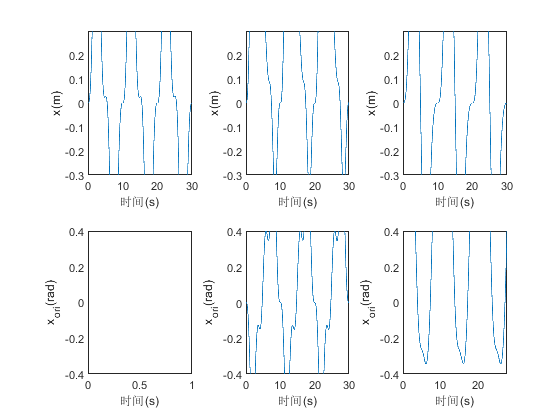

clear;clc;
load('T.mat');

load('x.mat');
% x=[-0.119242293890109,-0.0289952007175593,0.0664668994824977,0.0237079088008863,0.0580626863242845,0.0419773864521877,-0.00267401964624718,-0.0496190200512304,-0.0306534756622395,0.0469683231285912,0.0411113117407123,-0.115225578715347,0.219380623979779,-0.0343565297330836,-0.0289022449323917,-0.0408962705989567,-0.00499761007285050,-0.00207266669089688,0.000239057494393141,0.000582239626220017,0.00121936249331682,-0.00885669435096391,0.0813182183223835,-0.0469381354898080,-0.0219785436363902,-0.0346384496817463,0.0222369104855611,0.0552415012192290,-0.0935274579925923,-0.0156287844332455,0.0263374528574147,0.0146699913272066,0.0203504086964223,-0.225328769879010,0.110451522982307,0.00884642168516253,0.0546765083568324,0.0513543168547080,-0.0214935278437629,-0.0125428438974520,0.000185325129121677,0.00416695651934631,0.00587108283478151,-0.0405641689789603,0.192231955871549,-0.0420315868763289,-0.0549514250248446,-0.0658090243504607,-0.0294399196199141,0.0312571518037966,-0.00833241119050524,-0.0410402845438273,-0.0301571804267852,0.0458314491831682,0.0239334753876439,-0.0676132070237397,0.180990355053458,-0.127945569923376,-0.129163535244351,0.143731957138008,-0.00477933342526643,-0.00494119127039563,-0.000976654949269220,0.00141059037873975,0.00238986385978110,-0.0107347786414519;
% ];
a = [x(1:7),x(8:14),x(15:21),x(22:28),x(29:35)];  %7 by 5
b = [x(36:42),x(43:49),x(50:56),x(57:63),x(64:70)]; %7 by 5
c = x(71:77); %7 by 1
x1=[a(1,:)/2,b(1,:)/2,c(1,:)/2;a(2,:)/2,b(2,:)/2,c(2,:)/2;a(3,:)/3,b(3,:)/3,c(3,:)/3;a(4,:)/2,b(4,:)/2,c(4,:)/2;a(5,:)/2,b(5,:)/2,c(5,:)/2;a(6,:),b(6,:),c(6,:)];

d=zeros(7);
for o=1:7
    d(o)=c(o)-sum(b(1,:));
end
% h = 1/1250;    %采样周期 0.01s
h = 0.01;
T = 10;    %轨迹时间 10s
wf = 2*pi/10; %基频为0.1hz ~ 10s
N=5;          %5次傅里叶叠加
Phi = [];

save_t = [];
save_q = [];
save_q_dot = [];
save_q_ddot = [];

for t = 0:h:T
    q = c;
    q_dot = 0;
    q_ddot = 0;
    for l = 1:N
        q = q+a(:,l)*sin(l*wf*t)/(wf*l) - b(:,l)*cos(l*wf*t)/(wf*l);
        q_dot =  q_dot+a(:,l)*cos(l*wf*t) + b(:,l)*sin(l*wf*t);
        q_ddot = q_ddot-a(:,l)*l*wf*sin(l*wf*t) + b(:,l)*l*wf*cos(l*wf*t);
    end
    save_t = [save_t,t];
    save_q = [save_q,q];
    save_q_dot = [save_q_dot,q_dot];
    save_q_ddot = [save_q_ddot,q_ddot];
    
    Ys = Y_franka_symoro(q,q_dot,q_ddot);
    %Y = Ys*T_pinv;
    %Phi = [Phi;Y];
end

%Phi_cond = cond(Phi)

rate = 1.0;
save_q = save_q*rate;
save_q_dot = save_q_dot*rate;
save_q_ddot = save_q_ddot*rate;

period = 3;
save_q = [save_q,save_q,save_q];
save_q_dot = [save_q_dot,save_q_dot,save_q_dot];
save_q_ddot = [save_q_ddot,save_q_ddot,save_q_ddot];
save_t = [save_t,save_t+10,save_t+20];

globalJointCmdPos    = save_q;
globalJointCmdVel    = save_q_dot;
globalJointCmdAcc    = save_q_ddot;
globalEECmdForce     = zeros(size(globalJointCmdPos));
globalJointCmdTorque = zeros(size(globalJointCmdPos));
globalJointActPos    = zeros(size(globalJointCmdPos));
globalJointActVel    = zeros(size(globalJointCmdPos));
globalJointActTorque = zeros(size(globalJointCmdPos));
globalEEActForce     = zeros(size(globalJointCmdPos));
time                 = save_t;

%save_data = [save_t;save_q;save_q_dot;save_q_ddot];
%save_data = [globalJointCmdPos;globalJointCmdVel;globalJointCmdAcc;globalEECmdForce;globalJointCmdTorque;globalJointActPos;globalJointActVel;globalJointActTorque;time];
save_data = [globalJointCmdPos;globalJointCmdVel;globalJointCmdAcc;time];
save('data.mat','save_data');
dlmwrite('franka_data_read.txt',save_data);

% racer3_data_read.txt
% globalJointCmdPos    6
% globalJointCmdVel    6
% globalJointCmdAcc    6
% time                 1
% TOTAL:6*3+1=19 rows

q_max = max(save_q,[],2);
q_min = min(save_q,[],2);
q_dot_max = max(save_q_dot,[],2);
q_dot_min = min(save_q_dot,[],2);
q_ddot_max = max(save_q_ddot,[],2);
q_ddot_min = min(save_q_ddot,[],2);

% save_q(1,:)=save_q(1,:)/2;
% save_q(2,:)=save_q(2,:)/2;
% save_q(3,:)=save_q(3,:)/3;
% save_q(4,:)=save_q(4,:)/2;
% save_q(5,:)=save_q(5,:)/2;

figure(1)
for i = 1:3
    subplot(2,3,i)
    plot(save_t,save_q(i,:))
    %     title(['q',num2str(i)])
    xlabel('时间(s)')
    ylabel('x(m)')
    ylim([-0.3 0.3])
    
    subplot(2,3,i+3)
    plot(save_t,save_q(i+3,:))
    %     title(['q',num2str(i)])
    xlabel('时间(s)')
    ylabel('x_{ori}(rad)')
    ylim([-0.4 0.4])
end


% figure(2)
% for i = 1:7
%     subplot(3,3,i)
%     plot(save_t,save_q_dot(i,:))
%     title(['q_dot',num2str(i)])
% end
%
% figure(3)
% for i = 1:7
%     subplot(3,3,i)
%     plot(save_t,save_q_ddot(i,:))
%     title(['q_ddot',num2str(i)])
% end
%
% figure(4)
% plot3(save_q(1,:)/2,save_q(2,:)/2,save_q(3,:)/3)
% grid on;axis square;
